clc
clear all

data = load("carsuspensiondata.mat");

t = data.out.time;
u = data.out.u;
y = data.out.y;

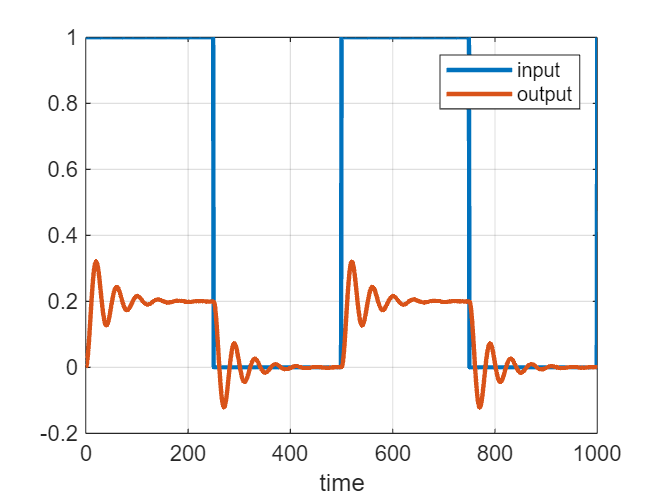

figure;
plot(t,u,t,y,LineWidth = 2)
grid on
xlabel('time')
legend('input', 'output')

Phi = [-y(2:end-1), -y(1:end-2), u(2:end-1), u(1:end-2)];
thetahat = Phi\y(3:end);

## One-Step Ahead Prediction

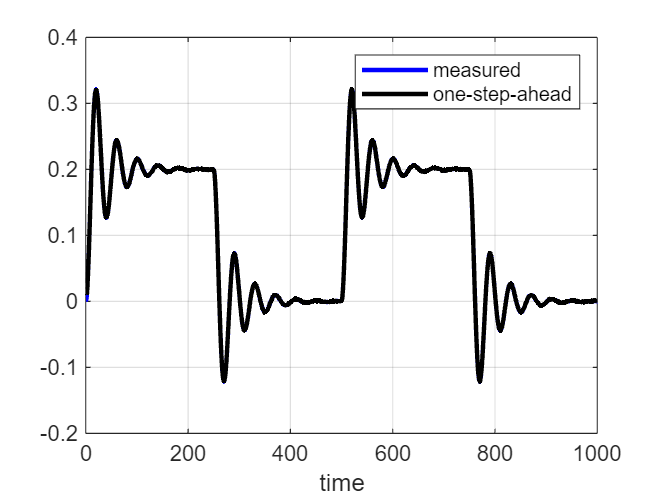

y_pred = Phi * thetahat;

figure;
plot(t,y,'b-',t(3:end),y_pred,'k-', 'LineWidth',2)
grid on
xlabel('time')
legend('measured', 'one-step-ahead')

## Simulation

N = length(u);
ysim = zeros(N,1);
for k = 3:N
    ysim(k) = [-ysim(k-1), -ysim(k-2), u(k-1), u(k-2)] * thetahat;
end

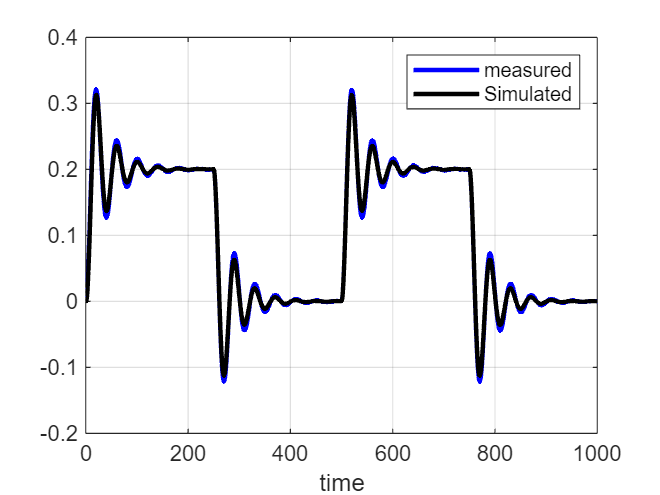

figure;
plot(t,y,'b-',t,ysim,'k-', 'LineWidth',2)
grid on
xlabel('time')
legend('measured', 'Simulated')